% clear
col_tot = 30;
row_tot = 30;
t = 1;
t_x = t;
t_y = t;
epsilon = 0;
% phi = 0.01;
Temperature = 0.01;
Disorder = 0.1;
phi = linspace(0, 2/(2*pi), 51);
% H_sparse = get_Nearest_Square_Hopping_Sparse(row_tot, col_tot, t_x, t_y);

x_operator = kron(spdiags((1:col_tot)', 0, col_tot, col_tot), speye(row_tot));
y_operator = kron(speye(col_tot), spdiags((1:row_tot)', 0, row_tot, row_tot));



tic;

%% KPM计算电导率

N_randvec = 10;
N_moments = 100;
N_points = 2 * N_moments;
chemical_potential = -3.5;
e_scaled = KPM_Chebyshev_abscissas(N_points);
Conductivity_xx = zeros(1, length(phi));
Conductivity_xy = zeros(1, length(phi));
% N_points = 1024;
for jj = 1:length(phi)
    jj
    H_sparse = Hamiltonian_2D_Real(col_tot, row_tot, epsilon, phi(jj), t);
    H_sparse = H_sparse + spdiags(Disorder * (rand(col_tot*row_tot,1)-0.5),0,col_tot*row_tot,col_tot*row_tot);
    v_operator_x = 1i * sparse(H_sparse * x_operator - x_operator * H_sparse);
    v_operator_y = 1i * sparse(H_sparse * y_operator - y_operator * H_sparse);
    [H_tilde, a, b] = KPM_scaleHamiltonian(H_sparse);
    
    energies = e_scaled * a + b;
    
    Moments_Mat = KPM_Moments_Correlator(H_tilde, N_randvec, N_moments, v_operator_x, v_operator_x, 'gpu');
    Moments_Kernel = KPM_Kernel_Correction(Moments_Mat, N_moments,'Lorentz');
    
    integral_factor = zeros(1, length(energies));
    
    for ii = 1:length(e_scaled)
        Gamma = KPM_Correlator_basis(e_scaled(ii), N_moments);
        integral_factor(ii) = tensorprod(Moments_Kernel, Gamma.','all');
    end
    
    
    fermi_distribution = KPM_fermi_distribution(energies, chemical_potential, Temperature);
    integrand = (fermi_distribution ./ ((1 - e_scaled.^2).^2)) .* integral_factor;
    integral = trapz(e_scaled, integrand);
    Conductivity_xx(jj) = (8 / a^2) * integral;
    

    Moments_Mat = KPM_Moments_Correlator(H_tilde, N_randvec, N_moments, v_operator_x, v_operator_y);
    Moments_Kernel = KPM_Kernel_Correction(Moments_Mat, N_moments,'Lorentz');

    integral_factor = zeros(1, length(energies));

    for ii = 1:length(e_scaled)
        Gamma = KPM_Correlator_basis(e_scaled(ii), N_moments);
        integral_factor(ii) = tensorprod(Moments_Kernel, Gamma.','all');
    end
    fermi_distribution = KPM_fermi_distribution(energies, chemical_potential, Temperature);
    integrand = (fermi_distribution ./ ((1 - e_scaled.^2).^2)) .* integral_factor;
    integral = trapz(e_scaled, integrand);
    Conductivity_xy(jj) = (8 / a^2) * integral;
end

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

jj = 8

jj = 9

jj = 10

jj = 11

jj = 12

jj = 13

jj = 14

jj = 15

jj = 16

jj = 17

jj = 18

jj = 19

jj = 20

jj = 21

jj = 22

jj = 23

jj = 24

jj = 25

jj = 26

jj = 27

jj = 28

jj = 29

jj = 30

jj = 31

jj = 32

jj = 33

jj = 34

jj = 35

jj = 36

jj = 37

jj = 38

jj = 39

jj = 40

jj = 41

jj = 42

jj = 43

jj = 44

jj = 45

jj = 46

jj = 47

jj = 48

jj = 49

jj = 50

jj = 51


toc;

历时 38.178142 秒。


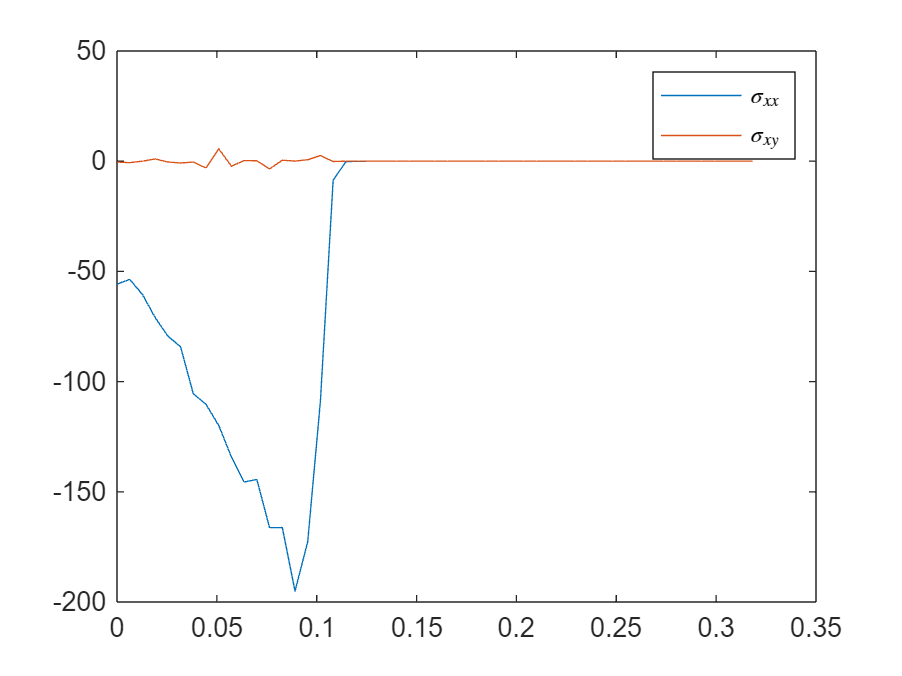


plot(phi, real(Conductivity_xx), phi, real(Conductivity_xy));
% axis([0,0.25/(2*pi),-100,100])
legend({'$\sigma_{xx}$','$\sigma_{xy}$'},'Interpreter','latex')

function H = Hamiltonian_2D_Real(Length, Width, epsilon, phi, t)
    
    H_00 = sparse(epsilon * eye(Width) - t * diag(ones(1, Width-1),1) - t * diag(ones(1, Width-1),-1));
    H_01 = sparse(-t * diag(exp(1i * 2*pi* (1:Width) * phi)));

    H = kron(speye(Length), H_00) + kron(spdiags(ones(Length, 1),1, Length, Length), H_01') + kron(spdiags(ones(Length, 1),-1, Length, Length), H_01);
    

end
